# Interpolate Path From Waypoints

Copyright 2021 The MathWorks, Inc

This script shows how to interpolate bettween cartesian waypoint locations in order to obtain smoother trajectories for UGV. [Common interpolation techniques](https://www.mathworks.com/help/matlab/referencelist.html) such as [Spline](https://www.mathworks.com/help/matlab/ref/spline.html), [Modified Akima](https://www.mathworks.com/help/matlab/ref/makima.html), and [PCHIP](https://www.mathworks.com/help/matlab/ref/pchip.html) are demosntrated as means of deriving smooth intermediate locations between critical navigation waypoints.

### Declare Waypoints, Create X Coordinates and Set Discretization

numPoints = 20; % Number of total points for trajectory
waypoints = [1 0;1.2 1.3;2.5 1.3;3 2.8;4 4]; % Original waypoints
pathX = linspace(waypoints(1,1),waypoints(end,1),numPoints);


### Use Spline, Makima and Pchip interpolation to calculate intermediate coordinates

sPathY = spline(waypoints(:,1),waypoints(:,2),pathX);
mPathY = makima(waypoints(:,1),waypoints(:,2),pathX);
pPathY = pchip(waypoints(:,1),waypoints(:,2),pathX);

### Plot Different Cartesian Trajectories

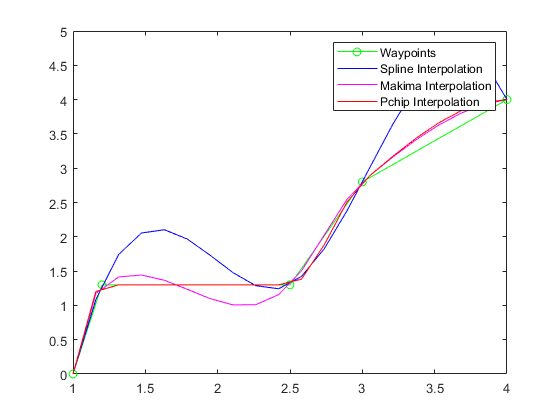

plot(waypoints(:,1),waypoints(:,2),'go-',pathX,sPathY,'b-',...
    pathX,mPathY,'m-',pathX,pPathY,'r-')
legend('Waypoints','Spline Interpolation','Makima Interpolation','Pchip Interpolation')

### Create Waypoint Arrays for Simulaiton

mTrajWaypoints = [pathX' mPathY'];
sTrajWaypoints = [pathX' sPathY'];
pTrajWaypoints = [pathX' pPathY'];